# Euler Bernoulli beam with cubic spring and damper

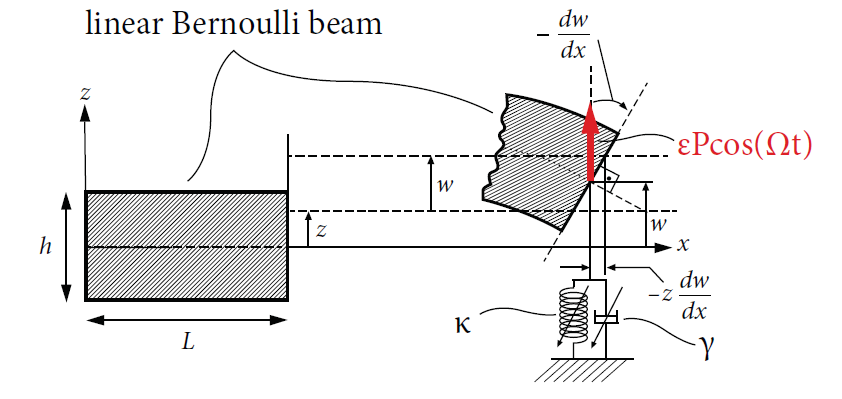

## generate model

nElements = 5;
kappa = 4; % cubic spring
gamma = 0; % cubic damping
[M,C,K,fnl,f_0] = build_model(kappa, gamma, nElements);
n = length(M);

## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',100,'notation','tensor')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


epsilon = 0.002;

Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 8.840017e-04
modal damping ratio for 2 mode is 5.488086e-03
modal damping ratio for 3 mode is 1.541080e-02
modal damping ratio for 4 mode is 3.044305e-02
modal damping ratio for 5 mode is 5.052761e-02

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.0700i
  -0.0001 - 0.0700i
  -0.0024 + 0.4389i
  -0.0024 - 0.4389i
  -0.0190 + 1.2327i
  -0.0190 - 1.2327i
  -0.0741 + 2.4343i
  -0.0741 - 2.4343i
  -0.2042 + 4.0370i
  -0.2042 - 4.0370i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i

sigma_in = 3300


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 3; % SSM approximation order
outdof = [n-2 n-1]; % degree of freedom at which output is displayed


setup options

set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 100, 'nPsi', 100, 'rhoScale', 2 )
set(S.FRCOptions, 'method','continuation ep') % 'level set' 
set(S.FRCOptions, 'outdof',outdof)

choose frequency range

omega0 = imag(S.E.spectrum(1));
omegaRange = omega0*[0.95 1.05];

extract forced response curve

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i

sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i
  -0.0062 

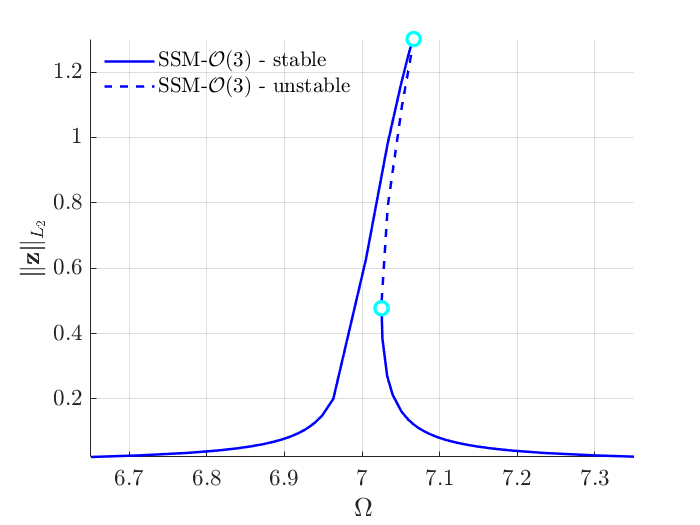

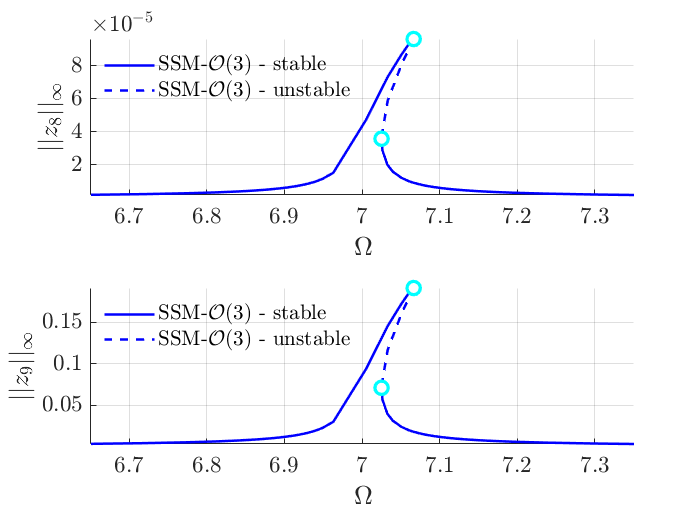

FRC = S.extract_FRC('freq',omegaRange,order);

figFRC = gcf;